# Using the FAµST API in Algorithms

After the little tour we've done in the previous live scripts, about the creation of Faust objects, and their manipulation, we shall see in this third live script how the FAµST API can be deployed seamlessly in algorithms. Our example, already alluded in the second live script, will be the Orthogonal Matching Pursuit algorithm (OMP).

This algorithm intervenes in the dictionary learning problem. Of  course, I will not treat the theory behind but I assume the reader is  already familiar with it. There is not so much to say so let's go straight to the code example.

**1. The Toy OMP Algorithm Implementation**

You'll find the implementation we're talking about here: [tomp.mlx](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Use_of_Faust_objects_in_algorithms.html#1.-The-Toy-OMP-Algorithm-Implementationhttps://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/tomp.mlx).

The most important point to notice in this code is that except the  import part in the header, all the code seems to be a natural numpy  implementation of OMP.

This is in fact the core philosophy of the FAµST API, as explained in  previous live scripts and also in the API documentation, we made sure that a Faust can be seen as a numpy array (or rather as a `numpy.matrix`) hence this code is in fact totally compatible with the two APIs: the  function argument D, which is the dictionary, can be indifferently a `pyfaust.Faust` object or a `numpy.matrix` object.

A secondary point is that this implementation is more like a toy concept (as indicated by the "t" in the function name). A more advanced and  optimized version is introduced in the last part of this live script and in particular allows to define the algorithm stopping criterion according to the error tolerance the user wants.

Next we will test this implementation in both cases. But first, let us define a test case.

**2. The Test Case Dictionary**

For convenience, we shall set up a dictionary which guarantees  uniqueness of sufficiently sparse representations. The dictionary is the concatenation of an identity matrix and a Hadamard matrix, and because we work with Faust objects, this concatenation will be a Faust object.

Below is the block matrix of our dictionary:


$$D=\;\lbrack \;I_n \mid H_n \rbrack \;$$


$I_n$ is the identity or Dirac matrix and$H_n \;$the orthonormal Hadamard matrix, with n being a power of two.

The condition on which the uniqueness of the sparse representation *x* of a vector *y*  is ensured is defined by the following inequality:

$\|\;x\;{\left\|\right.}_0 <\frac{\left(1+\frac{1\;}{\mu }\right)}{\;2}$ where *μ* denotes the coherence of the dictionary and in case of our specially crafted dictionary $\mu =\frac{1\;}{\;\sqrt{\;n}}$.

.

So let's construct the Faust of D, compute y for a sparse enough x  and test our OMP implementation to find out if we effectively retrieve  this unique x as we should according to this theorem.

Note that, for a better view and understanding you might consult this article [1].

n = 128;
FD = [ matfaust.eye(n), matfaust.wht(n) ];
D = full(FD)

D =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

Now that we have our dictionary both defined as a Faust (FD) and as a  matrix (D), let's construct our reference sparse vector x, we'll call it $x_0$.

x0 = zeros(2*n, 1);
nnz = floor(.5*(1+sqrt(n)));
nonzero_inds = randperm(2*n);
nonzero_inds = nonzero_inds(1:nnz)

nonzero_inds =    226   126   250   155    47   112


% we got nnz indices, now build the vector x0
x0(nonzero_inds, 1) = abs(randn(size(nonzero_inds,2), 1));
disp(strcat('l0 norm of x0: ', int2str(size(nonzeros(x0),1))))

l0 norm of x0:6


It remains to compute *y*.

y = D*x0;

Our test case is complete, we are fully prepared to run the OMP  algorithm using a well-defined dictionary as a Faust or as numpy array,  this should retrieve our $x_0$

 from the vector y. Let's try!

**3. Running the Algorithm**

x = tomp(y, FD, nnz);
nonzeros(x)

ans =     0.0104
    0.0104


nonzeros(x0)

ans =     0.3284
    0.8511
    1.2117
    1.3856
    0.0095
    0.3390


[I, ~, ~] = find(x-x0)

I =     47
   112
   126
   155
   226
   250


[I, ~, ~] = find(x)

I =    126
   155


assert(all(x-x0 < 10^-6));
disp('We succeeded to retrieve x0, OMP works!')

We succeeded to retrieve x0, OMP works!


We tested OMP on a Faust, go ahead and verify what I was aiming at in  the first part of the live script: is this OMP implementation really  working identically on a Faust and a real array.

x = tomp(y, D, nnz);
assert(all(x-x0 < 10^-6));
disp('We succeeded to retrieve x0, OMP works!')

We succeeded to retrieve x0, OMP works!


We can conclude that the algorithm is indeed available to both Matlab array and Faust worlds, and we can imagine surely that other algorithms are  reachable through the FAµST API. That's anyway in that purpose that the  FAµST library will be extended if needed in the future.

**4. An OMP-Cholesky Implementation**

Speaking of the OMP algorithm and the possibility to implement other  optimization algorithms with FAµST, it would be a pity not to mention that the library is delivered with another implementation of OMP.

This implementation is actually an optimized version which takes  advantage of the Cholesky factorization to simplify the least-square problem to solve at each iteration. This algorithm is implemented into the `tools` module of matfaust.

import matfaust.tools.omp
help matfaust.rand

 > @brief Generates a random Faust.
 >
 > @warning if this function is imported through 'import matfaust.rand' or 'import matfaust.*' the Matlab builtin function rand will be unreachable (matfaust.rand will be called instead). So it is not advisable to import this function, rather directly call matfaust.rand without any import.
 >
 > @b Usage
 >
 >   @b rand(@b M,@b N) generates a M-by-N Faust object. The numbers of rows and columns of intermediary factors are all randomly chosen between M and N (included). The number of factors is 5. The factors are sparse and real. The nnz per row of factors is 5.
 >
 >   @b rand(@b M, @b N, @b 'num_factors', @b NF, @b 'dim_sizes', @b S) with NF and S two integers, generates a M-by-N Faust of NF factors. The factor size is S for both dimensions (except the first factor number 

This implementation is integrated into matfaust as a tool for the Brain Source Localization (BSL) demo which is documented [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1demo_1_1bsl.html).

To show off a little, let's run this demo.

**Warning**: the demo takes a few minutes.

matfaust.demo.bsl.BSL()

Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. Exact signal representation found!
Stopping. 

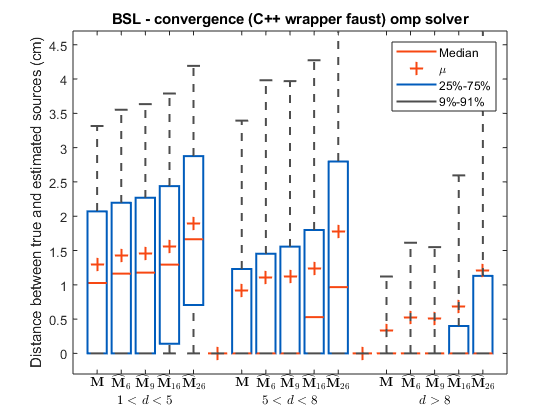

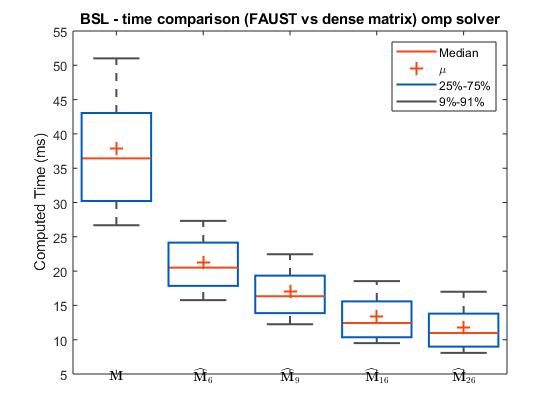

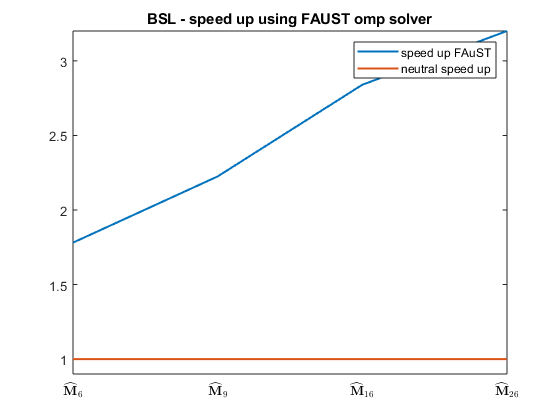

**** MEG with OMP solver time comparison ****
M tps : 37.8454
M_6 tps : 21.2477, speed-up : 1.7812
M_9 tps : 17.0064, speed-up : 2.2254
M_16 tps : 13.3245, speed-up : 2.8403
M_26 tps : 11.8238, speed-up : 3.2008


matfaust.demo.bsl.Fig_BSL()

What we see in this figure is that it takes a few dozens of milliseconds (the median time) to compute the BSL experiment on the dense matrix M.  This is well above the time it takes with Faust approximates$\hat{M_6 }$to$\hat{M_{26} }$.

 in which the numbers 6 and 26 denote the Faust [RCG](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#aff3261319b63c49d51a699726edc74bc). The greater the RCG the better the computation time is, as we already saw in the live script[ about Faust manipulations](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Use_of_Faust_objects_in_algorithms.html#manip_links).

As a complementary test, let's verify that the two runs of `omp()` on FD and D we constructed before for the toy omp give the same results even if the vector to retrieve is not very sparse. Here for instance, $\left\|\;x_1 \;{\left\|\right.}_0 =98\right.$.

import matfaust.tools.omp
nnz = 98;
x1 = zeros(2*n, 1);
nnz_inds = randperm(2*n);
nnz_inds = nnz_inds(1:nnz);
x1(nnz_inds, 1) = randn(size(nnz_inds,2),1);
y = FD*x1;
x2 = omp(y, D, 'maxiter', nnz);
x3 = omp(y, FD, 'maxiter', nnz);
disp(['Are x2 and x3 solutions almost equal? ' int2str(norm(x2-x3)/norm(x3) < 10^-12) ])

Are x2 and x3 solutions almost equal? 1


disp(['Is x1 retrieved into x2? ' int2str(all(x1-x2 < 10^-6)) ])

Is x1 retrieved into x2? 0


disp(['Is x1 retrieved into x3? ' int2str(all(x1-x3 < 10^-6)) ])

Is x1 retrieved into x3? 0


As expected, we didn't retrieve our starting x1 (the reason is the condition already discussed in 2. However let's mention that here again (like it was with the toy OMP) it works the same with the Faust API or with Matlab arrays.

Finally, let's check the computation time for applying our dictionary to a vector both for the Matlab and Faust versions. Although, in order  to avoid major differences in results calculated on distinct computer  configurations the comparison is performed on a larger dimension than  before.

n = 1024;
FD = [ matfaust.eye(n) matfaust.wht(n) ];
D = full(FD);
x = rand(2*n, 1);
timeit(@() D*x)

ans = 0.0037

timeit(@() FD*x)

ans = 6.4287e-04

For a dimension as smaller than 128, it's possible on particular  machines to obtain a slower FD multiplication comparatively to the D  multiplication.

This is essentially because the speedup offered by Faust appears rather for higher matrix dimensions.

Let us illustrate the speedup more generally by repeating the experiment for various dimensions n.

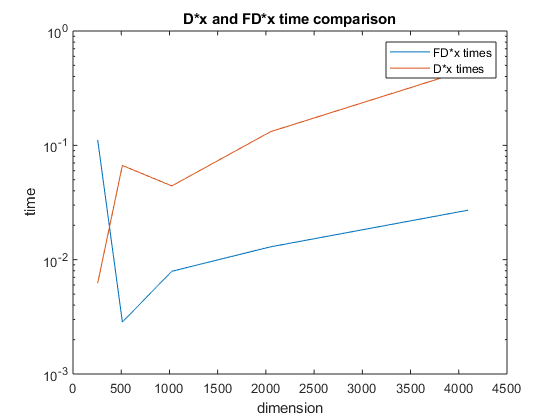

figure()
d_times = [];
fd_times = [];
dims = [];
num_muls = 10;
for n=2.^(8:12)
    FD = [ matfaust.eye(n) matfaust.wht(n) ];
    D = full(FD);
    x = randn(2*n, 1);
    dims = [dims n];
    t=tic;
    for i=1:num_muls
        D*x;
    end
    d_times = [ d_times toc(t)];
    t=tic;
    for i=1:num_muls
        FD*x;
    end
    fd_times = [ fd_times toc(t)];
end
semilogy(dims, fd_times, dims, d_times);
legend("FD*x times", "D*x times")
xlabel("dimension")
ylabel("time")
title("D*x and FD*x time comparison")

As shown for dimensions n above 1024 an actual speedup occurs, the  speedup figure below confirms this result. Improving such a speedup and decreasing the dimensions where it occurs  is part of the roadmap for future developments of matfaust.

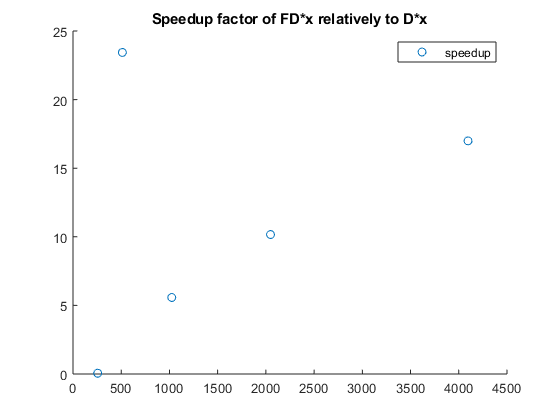

scatter(dims, d_times./fd_times)
legend('speedup') 
title("Speedup factor of FD*x relatively to D*x")

***The third live script is ending here***, I hope  you'll be interested in trying yourself to write another algorithm with  the FAµST API and maybe discovering any current limitation. Don't  hesitate to contact us in that case, we'll appreciate any feedback!

**Links**

Faust creation (1st) live script:  [html](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.mlx.html), [mlx](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.mlx)

Faust manipulation (2nd) live script: [html](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_manipulation.mlx.html), [mlx](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_manipulation.mlx)

[1] [Tropp, J. A. (2004). Greed is Good: Algorithmic Results for Sparse  Approximation. IEEE Transactions on Information Theory, 50(10),  2231–2242](http://doi.org/10.1109/TIT.2004.834793).